clear;
close all;
clc;

%% Robot parameters

param = robot_parameters();

%% Initial state

q0 = [
    deg2rad(120);
    deg2rad(60)
];

dq0 = [
    0;
    0
];

x0 = [
    q0;
    dq0
];

%% Simulation settings

tspan = [0, 10.0];

options = odeset( ...
    'RelTol', 1e-7, ...
    'AbsTol', 1e-9, ...
    'MaxStep', 2e-4);

%% Run simulation
%
% Contact stiffness can make the system numerically stiff.
% ode15s is therefore used here.

[t, x] = ode15s( ...
    @(t, x) forward_dynamics_MCGFC( ...
        t, x, param), ...
    tspan, ...
    x0, ...
    options);

%% Extract states

q  = x(:, 1:2);
dq = x(:, 3:4);

number_of_samples = length(t);

%% Allocate logs

ddq = zeros(number_of_samples, 2);

ee_position = zeros(number_of_samples, 2);
ee_velocity = zeros(number_of_samples, 2);

contact_force = zeros(number_of_samples, 2);
contact_torque = zeros(number_of_samples, 2);

penetration = zeros(number_of_samples, 1);
contact_state = false(number_of_samples, 1);

friction_torque_log = zeros(number_of_samples, 2);

kinetic_energy = zeros(number_of_samples, 1);
potential_energy = zeros(number_of_samples, 1);
mechanical_energy = zeros(number_of_samples, 1);

%% Recalculate and log dynamics

for k = 1:number_of_samples

    q_k  = q(k, :).';
    dq_k = dq(k, :).';

    %% Dynamics

    M_k = mass_matrix(q_k, param);

    c_k = coriolis_torque( ...
        q_k, dq_k, param);

    G_k = gravity_torque( ...
        q_k, param);

    tau_fric_k = friction_torque( ...
        dq_k, param);

    %% Contact

    [F_contact_k, tau_contact_k, contact_detail] = ...
        surface_contact_force( ...
            q_k, dq_k, param);

    %% No command torque

    tau_command_k = [
        0;
        0
    ];

    %% Acceleration

    ddq_k = M_k \ ( ...
        tau_command_k ...
        + tau_contact_k ...
        - c_k ...
        - G_k ...
        - tau_fric_k);

    %% Mechanical energy

    kinetic_energy(k) = ...
        0.5 * dq_k.' * M_k * dq_k;

    potential_energy(k) = ...
        param.m1 ...
        * param.g ...
        * param.r1 ...
        * sin(q_k(1)) ...
        + param.m2 ...
        * param.g ...
        * ( ...
            param.l1 * sin(q_k(1)) ...
            + param.r2 * sin(q_k(2)));

    mechanical_energy(k) = ...
        kinetic_energy(k) ...
        + potential_energy(k);

    %% Store

    ddq(k, :) = ddq_k.';

    ee_position(k, :) = [
        contact_detail.x_ee, ...
        contact_detail.z_ee
    ];

    ee_velocity(k, :) = [
        contact_detail.vx_ee, ...
        contact_detail.vz_ee
    ];

    contact_force(k, :) = ...
        F_contact_k.';

    contact_torque(k, :) = ...
        tau_contact_k.';

    penetration(k) = ...
        contact_detail.penetration;

    contact_state(k) = ...
        contact_detail.is_contact;

    friction_torque_log(k, :) = ...
        tau_fric_k.';

end

%% Results

disp('Maximum penetration [mm]');

Maximum penetration [mm]


disp(1000 * max(penetration));

   12.1375




disp('Maximum normal contact force [N]');

Maximum normal contact force [N]


disp(max(contact_force(:, 2)));

   69.3600




disp('Final end-effector height [m]');

Final end-effector height [m]


disp(ee_position(end, 2));

   -0.0117




disp('Floor height [m]');

Floor height [m]


disp(param.z_floor);

   -0.0100




disp('Final joint angles [deg]');

Final joint angles [deg]


disp(rad2deg(q(end, :)));

  271.3627   76.0540




disp('Final joint velocities [rad/s]');

Final joint velocities [rad/s]


disp(dq(end, :));

   -0.0062    0.0008



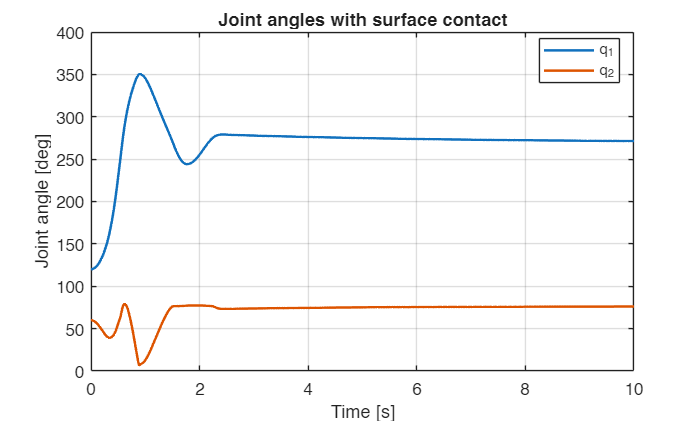


%% Joint angles

figure;

plot(t, rad2deg(q(:, 1)), ...
    'LineWidth', 1.5);

hold on;

plot(t, rad2deg(q(:, 2)), ...
    'LineWidth', 1.5);

grid on;

xlabel('Time [s]');
ylabel('Joint angle [deg]');

legend('q_1', 'q_2', ...
    'Location', 'best');

title('Joint angles with surface contact');

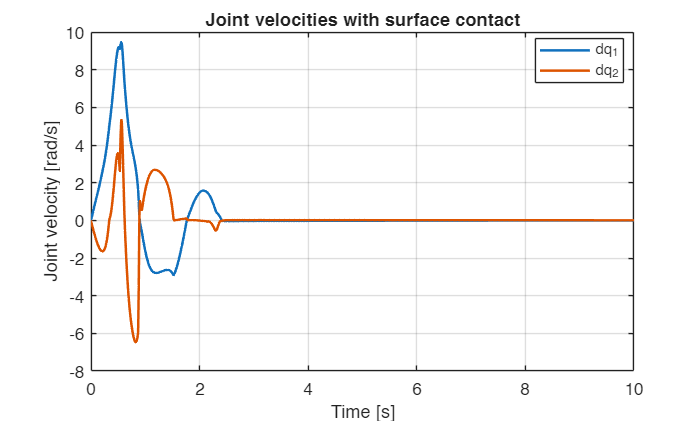


%% Joint velocity

figure;

plot(t, dq(:, 1), ...
    'LineWidth', 1.5);

hold on;

plot(t, dq(:, 2), ...
    'LineWidth', 1.5);

grid on;

xlabel('Time [s]');
ylabel('Joint velocity [rad/s]');

legend('dq_1', 'dq_2', ...
    'Location', 'best');

title('Joint velocities with surface contact');

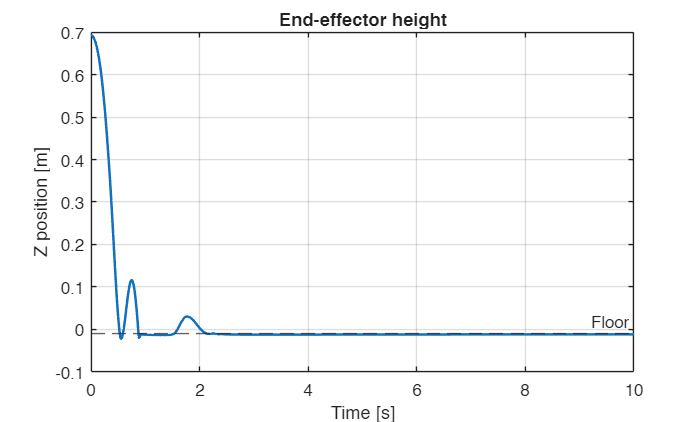


%% End-effector height

figure;

plot(t, ee_position(:, 2), ...
    'LineWidth', 1.5);

hold on;

yline( ...
    param.z_floor, ...
    '--', ...
    'Floor');

grid on;

xlabel('Time [s]');
ylabel('Z position [m]');

title('End-effector height');

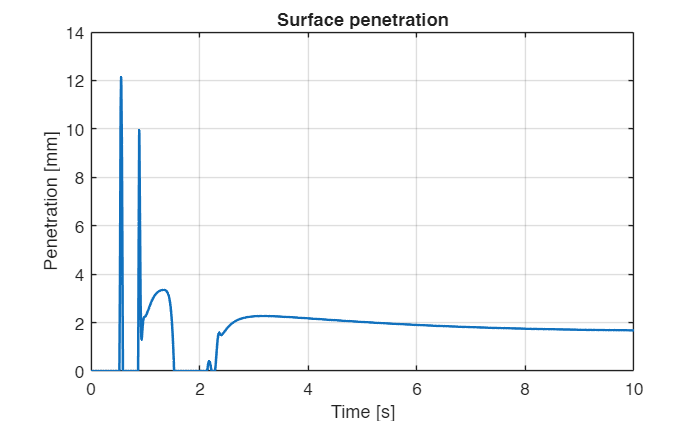


%% Penetration

figure;

plot(t, ...
    1000 * penetration, ...
    'LineWidth', 1.5);

grid on;

xlabel('Time [s]');
ylabel('Penetration [mm]');

title('Surface penetration');

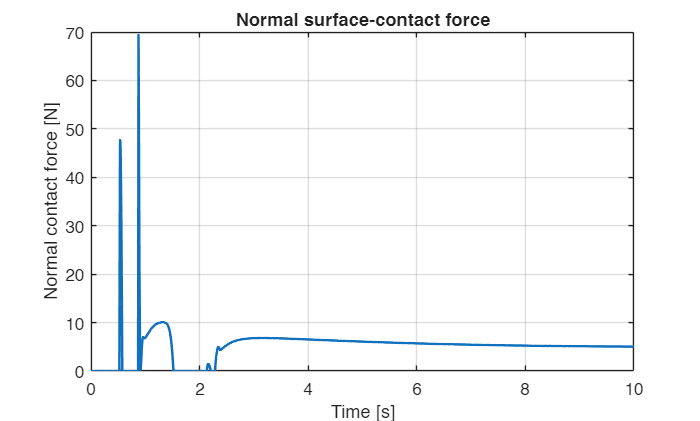


%% Contact force

figure;

plot(t, contact_force(:, 2), ...
    'LineWidth', 1.5);

grid on;

xlabel('Time [s]');
ylabel('Normal contact force [N]');

title('Normal surface-contact force');

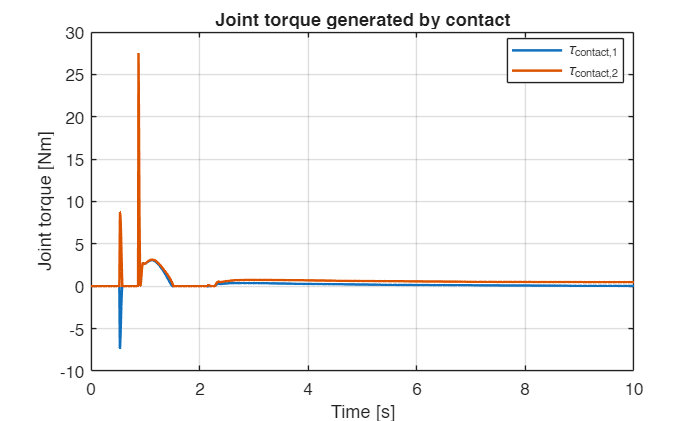


%% Contact joint torque

figure;

plot(t, contact_torque(:, 1), ...
    'LineWidth', 1.5);

hold on;

plot(t, contact_torque(:, 2), ...
    'LineWidth', 1.5);

grid on;

xlabel('Time [s]');
ylabel('Joint torque [Nm]');

legend( ...
    '\tau_{contact,1}', ...
    '\tau_{contact,2}', ...
    'Location', 'best');

title('Joint torque generated by contact');

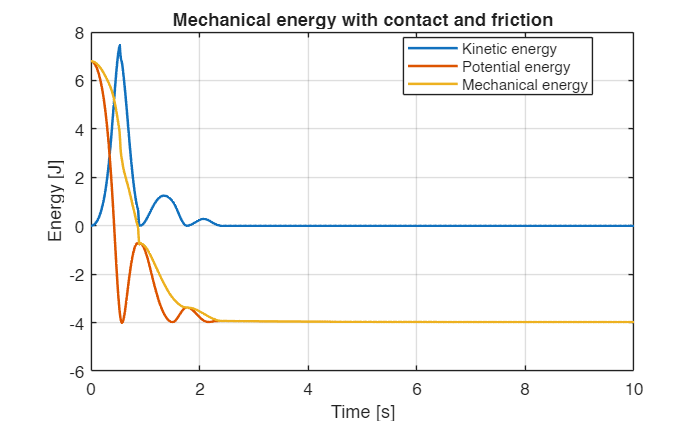


%% Mechanical energy

figure;

plot(t, kinetic_energy, ...
    'LineWidth', 1.5);

hold on;

plot(t, potential_energy, ...
    'LineWidth', 1.5);

plot(t, mechanical_energy, ...
    'LineWidth', 1.5);

grid on;

xlabel('Time [s]');
ylabel('Energy [J]');

legend( ...
    'Kinetic energy', ...
    'Potential energy', ...
    'Mechanical energy', ...
    'Location', 'best');

title('Mechanical energy with contact and friction');

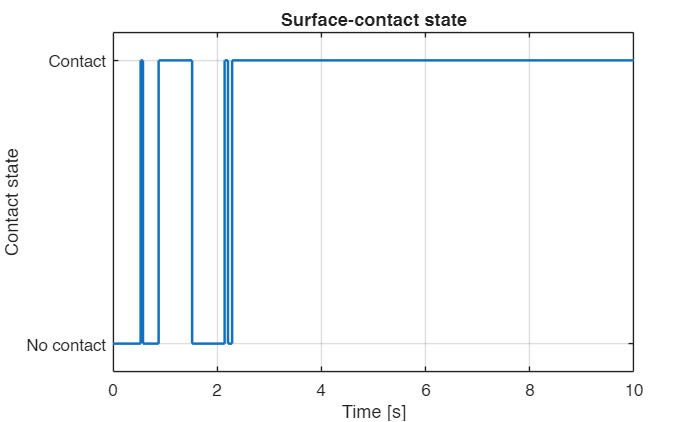


%% Contact state

figure;

stairs(t, double(contact_state), ...
    'LineWidth', 1.5);

grid on;

ylim([-0.1, 1.1]);

xlabel('Time [s]');
ylabel('Contact state');

yticks([0, 1]);
yticklabels({'No contact', 'Contact'});

title('Surface-contact state');

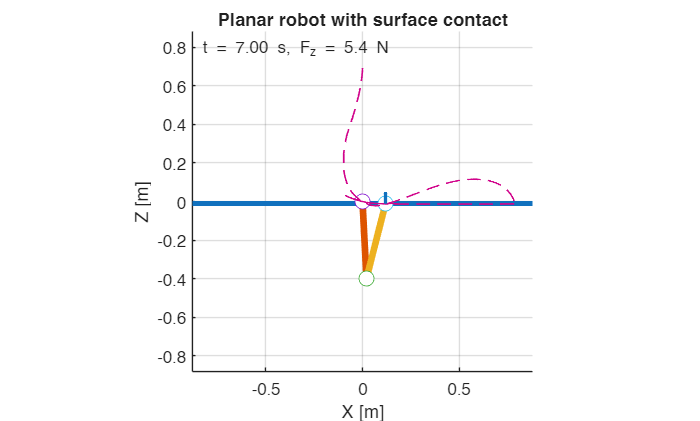


%% Animation

animate_planar_robot_with_floor( ...
    t, q, param);